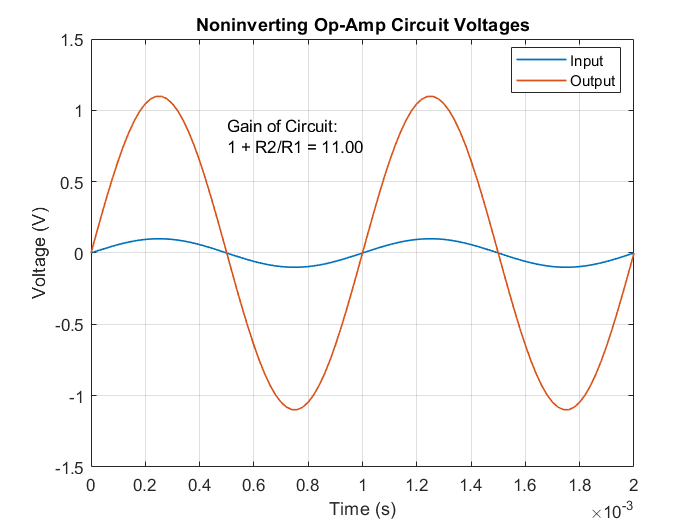

% Code to plot simulation results from ssc_opamp_noninverting

% Copyright 2015 The MathWorks, Inc.

% Reuse figure if it exists, else create new figure
try
    figure(h1_ssc_opamp_noninverting)
catch
    h1_ssc_opamp_noninverting=figure('Name', 'ssc_opamp_noninverting');
end

% Generate simulation results if they don't exist
if(~exist('simlog_ssc_opamp_noninverting','var'))
    sim('ssc_opamp_noninverting')
end

% Get simulation results
temp_vin = simlog_ssc_opamp_noninverting.AC_Voltage.v.series;
temp_vout = simlog_ssc_opamp_noninverting.Sensor_Vout.Voltage_Sensor.V.series;

% Plot results
plot(temp_vin.time,temp_vin.values,'LineWidth',1);
hold on
plot(temp_vout.time,temp_vout.values,'LineWidth',1);
hold off
text(0.5e-3,0.9,'Gain of Circuit:');
text(0.5e-3,0.75,sprintf('%s %2.2f','1 + R2/R1 =',max(temp_vout.values)/max(temp_vin.values)));
grid on
title('Noninverting Op-Amp Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
legend({'Input','Output'},'Location','Best');


% Remove temporary variables
clear temp_vin temp_vout